soft_folder = "soft_gripper_expts_2/";
soft_files = ["expt_2.mat";"expt_3.mat";"expt_5.mat";"expt_6.mat";"expt_10.mat"];

rigid_folder = "rigid_gripper_expts_2/";
rigid_files = ["expt_1.mat";"expt_2.mat";"expt_8.mat";"expt_9.mat";"expt_10.mat"];

% plot variables here
titlefsz = 20;
textfsz = 17;
axfsz = 15;
linewidth = 2;

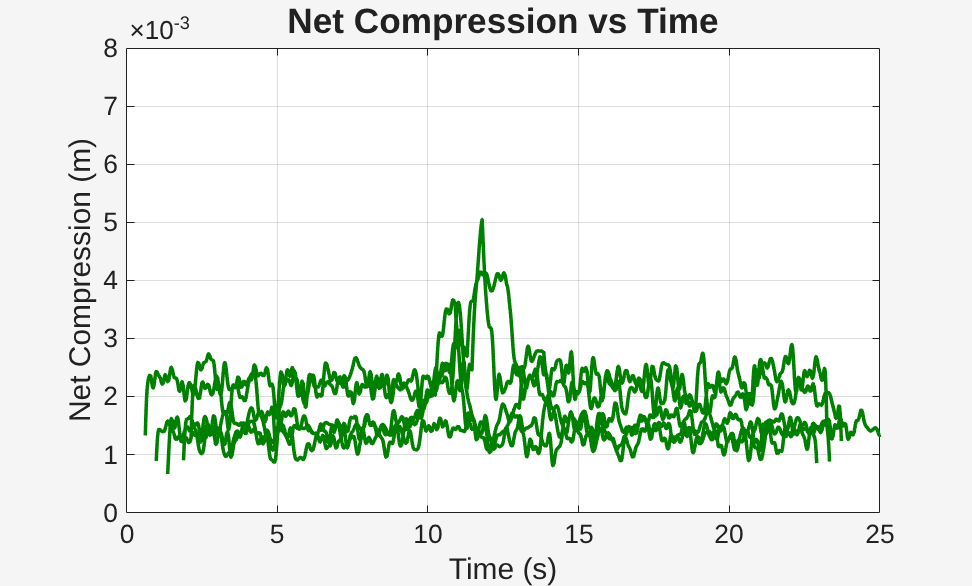

figure;
theme(figure,"light");

for i = 1:5
    % plot the soft gripper net deformation
    load(soft_folder + soft_files(i));
    net_x = enc(:,1) + enc(:,2);
    plot(ot,net_x,"Color",[0 0.5 0],"LineWidth",linewidth);
    hold on;
end

ax = gca;
ax.FontSize = axfsz;
xlabel("Time (s)","FontSize",textfsz);
ylabel("Net Compression (m)","FontSize",textfsz);
title("Net Compression vs Time","FontSize",titlefsz);
xlim([0,25]);
ylim([0,8e-3]);
grid on;
%legend(["Soft gripper","Rigid Gripper"]);
saveas(gcf,"soft_net_deformation.png");
hold off;

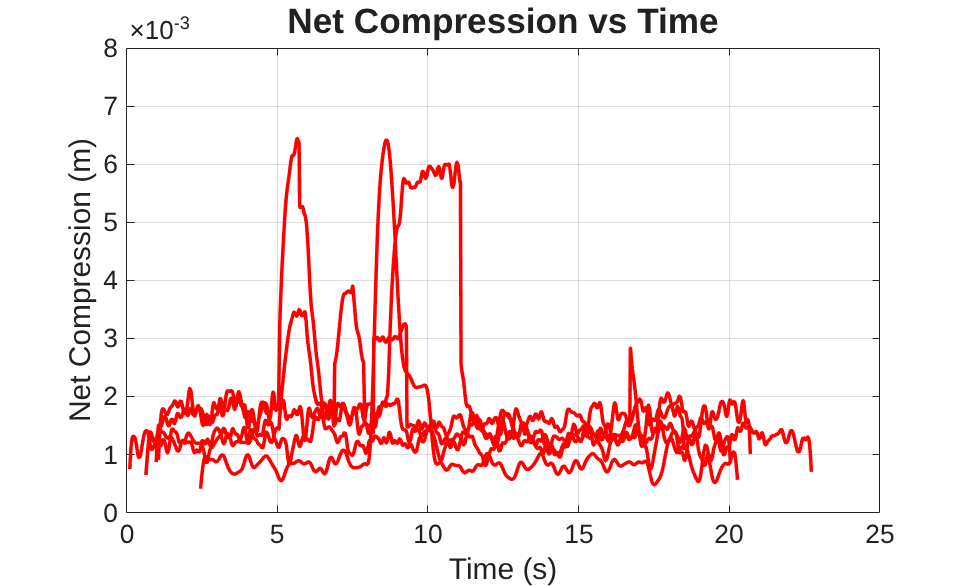



figure;
theme(figure,"light");

for i = 1:5
    % plot the rigid gripper net deformation
    load(rigid_folder + rigid_files(i));
    net_x = enc(:,1) + enc(:,2);
    plot(ot,net_x,"Color",[1 0 0],"LineWidth",linewidth);
    hold on;
end

ax = gca;
ax.FontSize = axfsz;
xlabel("Time (s)","FontSize",textfsz);
ylabel("Net Compression (m)","FontSize",textfsz);
title("Net Compression vs Time","FontSize",titlefsz);
xlim([0,25]);
ylim([0,8e-3]);
grid on;
%legend(["Soft gripper","Rigid Gripper"]);
saveas(gcf,"rigid_net_deformation.png");
hold off;

% plot(at,net_area',"LineWidth",linewidth,"Color",[0 0.5 0]);
% hold on;
% ax = gca;
% ax.FontSize = axfsz;
% xlabel('Time (s)','FontSize',textfsz);
% ylabel('Net Area (m^2)','FontSize',textfsz);
% title('Contact Area vs time','FontSize',titlefsz-2);
% xlim([0 25]);
% grid on;
% saveas(gcf,"Contact area over full experiment.png")
% hold off;